# **ACM 11 Homework 5 Part 1: Regression**

## Introduction

In this problem, we will use a auto data set from Tibshirani's *Introduction to Statistical Learning *to predict automobile performance, or to be more specific, whether a car will have high or low gas mileage. The data set, named as Auto, has 8 characteristics of 392 different vehicles: mpg, cylinders, displacement, horsepower, weight, acceleration, year and origin (1=American, 2 = European, 3 = Japanese). This file, Part 1, familiarizes you with the data set and asks you to fit a model using linear regression. In Part 2, you will use the same data set for classification.

## Problem 1: Load and explore the data set

**(1a) **Please load the ''Auto.csv" data set into matlab. Notice that the data set contains numbers and also strings (you may open the csv file to check first). The `READTABLE` function in MATLAB will be useful here. Note that `READTABLE` outputs a struct where each variable is a field of the struct. To access one of these fields, use the syntax `struct_name.field_name`.

clear; close all
T = readtable("Auto.csv");

**(1b)** We will consider the first 7 variables in the dataset: mpg, cylinders, displacement, horsepower, weight, acceleration, and year. To visualize these numerical variables, we will use the MATLAB function `PLOTMATRIX`. To use this function, you will have to create a matrix where each column corresponds to one of these variables. Hint: the MATLAB function TABLE2ARRAY may be useful. Calling `PLOTMATRIX` on this matrix will yield a plot with a 7x7 grid of subplots. The diagonal of this grid contains histograms of the values in the data set for each variable. The (i,j) off-diagonal plot displays a scatterplot of the values of the i-th variable vs. the j-th variable in your matrix. Label the x-axes of the bottom-most plots and the y-axes of the left-most plots with the variable names. Hint: [see this MATLAB Answer on how to add labels](https://www.mathworks.com/matlabcentral/answers/183203-add-label-to-sub-axes-in-plotmatrix#answer_282775).

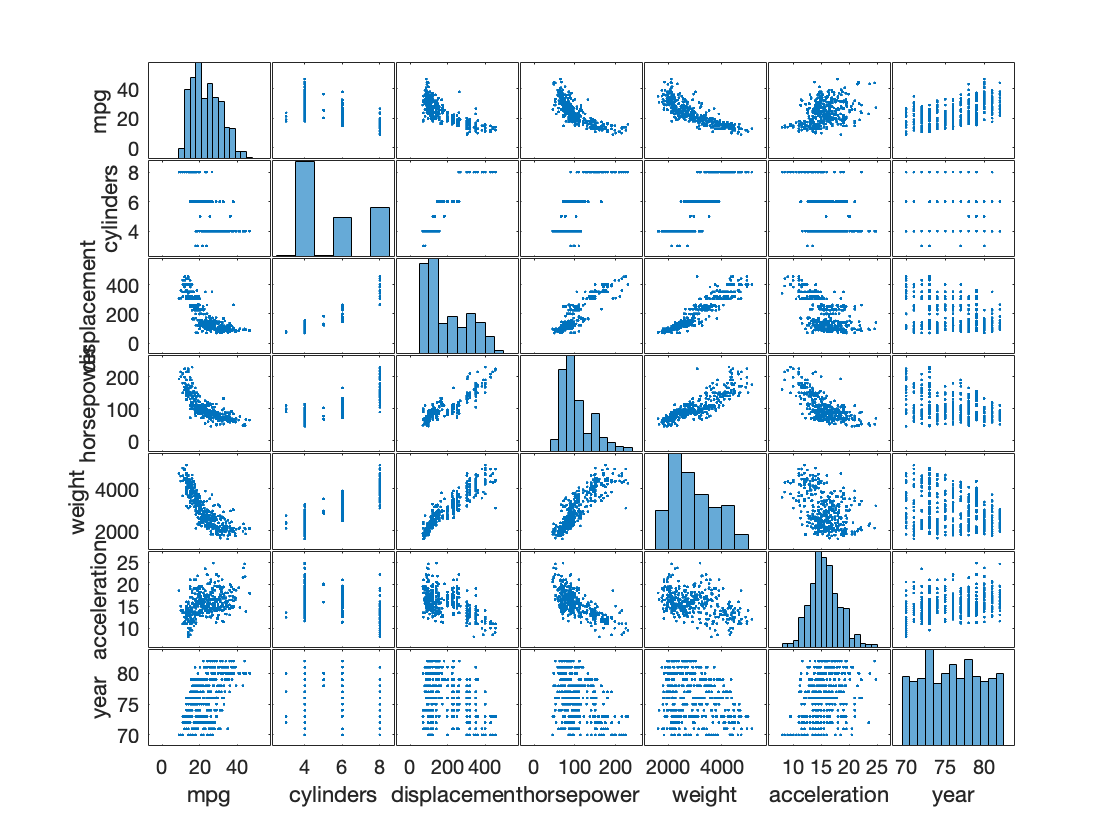

A = [T.mpg, T.cylinders, T.displacement, T.horsepower, T.weight, T.acceleration, T.year];

[~, ax] = plotmatrix(A);
ax(1,1).YLabel.String='mpg'; 
ax(2,1).YLabel.String='cylinders'; 
ax(3,1).YLabel.String='displacement'; 
ax(4,1).YLabel.String='horsepower'; 
ax(5,1).YLabel.String='weight'; 
ax(6,1).YLabel.String='acceleration'; 
ax(7,1).YLabel.String='year';

ax(7,1).XLabel.String='mpg'; 
ax(7,2).XLabel.String='cylinders'; 
ax(7,3).XLabel.String='displacement'; 
ax(7,4).XLabel.String='horsepower'; 
ax(7,5).XLabel.String='weight'; 
ax(7,6).XLabel.String='acceleration'; 
ax(7,7).XLabel.String='year';

**(1c) **From your plot in (1b), focus on the MPG column/row. Do any variables stand out has having positive correlation with MPG (ie if the variable goes up, MPG also goes up)? Negative correlation (if the variable goes down, MPG goes up)? No strong correlation?

positive correlation with: year

negative correlation with: displacement, horsepower, weight

no strong correlation with:  cylinder, acceleration

**(1d) **In (1c) we asked you to assess correlation by visual inspection of scatter plots. Now, we will compute correlation numerically using MATLAB's `CORR` function. Call `CORR` on the same matrix you called `PLOTMATRIX` on before. The result will be a 7x7 matrix containing values of correlation coefficients between the variables. You will see that the diagonal is made up of 1's - because a variable is by definition perfectly correlated with itself. 

C = corr(A)

C =     1.0000   -0.7776   -0.8051   -0.7784   -0.8322    0.4233    0.5805
   -0.7776    1.0000    0.9508    0.8430    0.8975   -0.5047   -0.3456
   -0.8051    0.9508    1.0000    0.8973    0.9330   -0.5438   -0.3699
   -0.7784    0.8430    0.8973    1.0000    0.8645   -0.6892   -0.4164
   -0.8322    0.8975    0.9330    0.8645    1.0000   -0.4168   -0.3091
    0.4233   -0.5047   -0.5438   -0.6892   -0.4168    1.0000    0.2903
    0.5805   -0.3456   -0.3699   -0.4164   -0.3091    0.2903    1.0000


Look at the row/column associated with MPG. Larger positive values mean stronger positive correlation with MPG; more negative values mean stronger negative correlation. Do these computed correlation coefficients match your observations above? Which variable has the strongest correlation (positive or negative) with MPG (ie largest absolute value of correlation coefficient, not including MPG itself)? Are any of your predictions to have no strong correlation suprising?

Yes they match my observations. Except for cylinder, according to the numbers it has a negative correlation with mpg but i wasn't able to interpret the graph so I assumed no correlation. The strongest correlation is with weight. The cylinder one is surprising since the graph looks so odd.

## **Problem 2: Fitting a model for MPG**

We would like to develop a simple model for predicting the MPG of a vehicle. To that end, we will fit a polynomial model to the variable you identified in Problem 1 as having the strongest correlation (positive or negative) with MPG. Let's call this variable $z$.

**(2a) **Let's start by dividing the available data into a training set and a test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ values of $z$ and MPG for training, and save the remaining values of $z$ and MPG for testing the fitted model.

n = 300;
z = A(:,5); % weight
mpg = A(:,1);

z_train = z(1:n);
z_test = z(n+1:end);
mpg_train = mpg(1:n);
mpg_test = mpg(n+1:end);

**(2b) **For polynomial orders $p=1,2,3,4,5$, fit a polynomial model of the form

$\textrm{MPG}\approx a_0 +a_1 x+\cdots +a_p x^p$.

Use the built-in function `POLYFIT` to find the coefficients $a_0 ,a_1 ,\dots ,a_p$.  Note that it will output a warning because there are likely many repeated values of $z$ in the data set. You can ignore this warning.

(i) Make a scatter plot of MPG vs. $z$. Give the points in the training set one color and the points in the test set another color. Then, for each $p$, plot the fitted polynomial as a line vs $z$. Label your axes and include an appropriate legend. Don't forget to find an appropriate set of limits for the x and y axes. You can change the limits using the MATLAB functions XLIM and YLIM.

(ii) For each $p$, calculate the mean squared error of your fitted polynomial model over both the training set and over the test set using the function `POLYVAL`. In separate axes, plot these errors vs. $p$. Label your axes and include an appropriate title.

% MPG vs weight
figure;
scatter(z_train, mpg_train, "green", "filled")
hold on
scatter(z_test, mpg_test, "magenta", "filled")

pmax = 5;
p = linspace(1, pmax, pmax);
err_train = zeros(pmax, 1);
err_test = zeros(pmax, 1);
x = linspace(1000, 6000, 1000);

for i=1:pmax
    a = polyfit(z_train, mpg_train, p(i));
    
    plot(x, polyval(a, x))
    
    poly_train = polyval(a, z_train);
    poly_test = polyval(a, z_test);
    
    err_train(i) = mean((poly_train - mpg_train).^2);
    err_test(i) = mean((poly_test - mpg_test).^2);
end

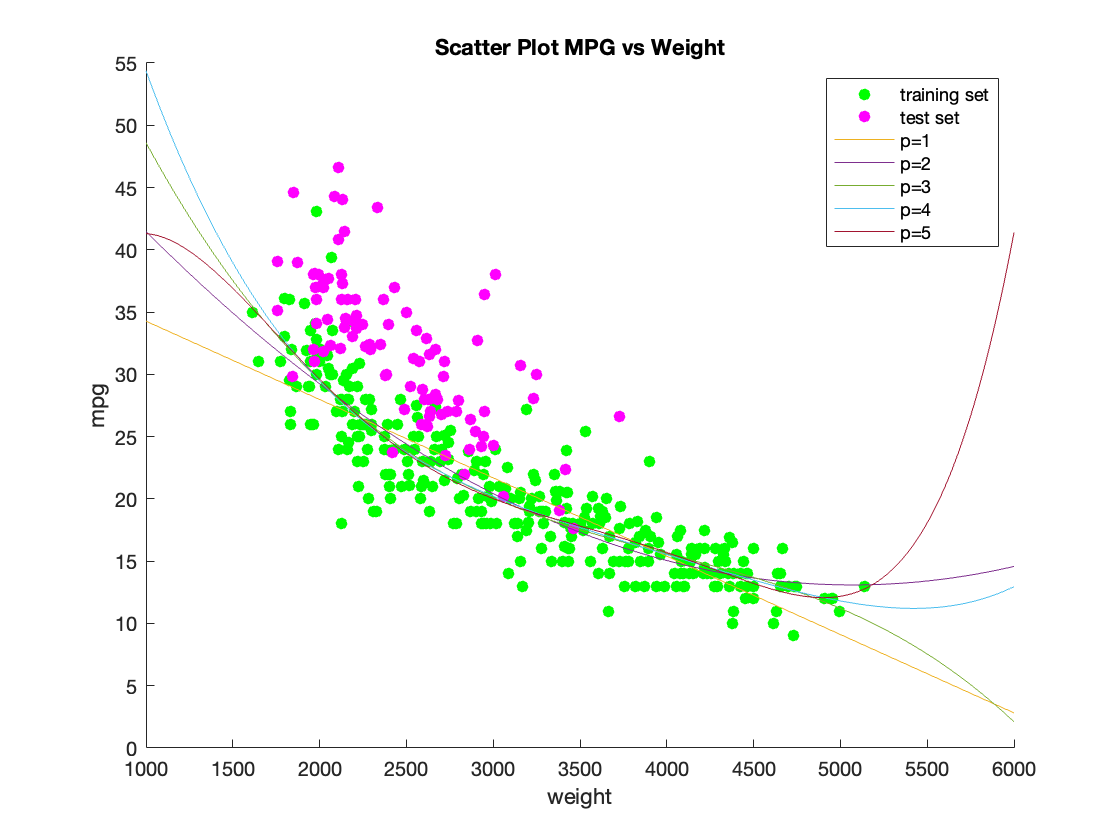


hold off
ylabel("mpg")
xlabel("weight")
legend("training set", "test set", "p=1", "p=2", "p=3", "p=4", "p=5", "Location", "northeast")
xlim([1000 6000])
ylim([0 55])
title("Scatter Plot MPG vs Weight")

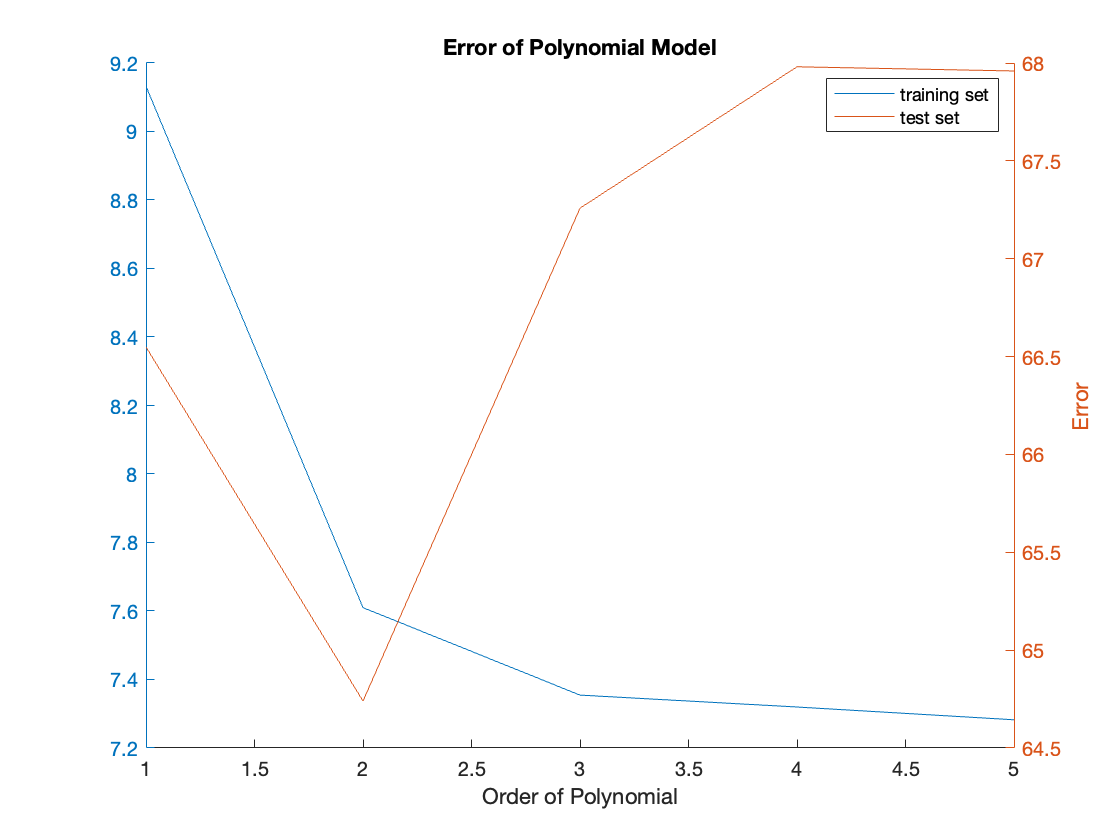


% error plot
figure;
hold on
yyaxis left
plot(p, err_train)
yyaxis right
plot(p, err_test)
hold off
xlabel("Order of Polynomial")
ylabel("Error")
legend("training set", "test set", "Location", "northeast")
title("Error of Polynomial Model")

**(2c)** How does the training error change as the order of the polynomial fit is changed? Why does this happen?

The training error decreases as the order of the polynomial fit increases. This is because it becomes more accurate and a closer fit for the training data.

**(2d)** How does the test error change as the order of the polynomial fit is changed? For what $p$ is this error minimized? In 1-2 sentences, explain why there are differences between the trends for the test error and for the training error. In particular, compare the test errors to the plot of the fitted polynomials.

As the order of the polynomial fit increases, the test error decreases at first and then starts increasing again. This error is minimized for p=2. The difference between the trends for the test and the training errors happens because if you increase the order of the polynomial too much it will be overfit and only work be accurate for the training model but not for the test model.